%%preparation of data
%%To simplify the original excel 'ISE599_Midterm.XLSX', I split the excel into 5 separate excel documents 
%'allname.xlsx': record all the names of assets follow the time series
%%'rebalance return.xlsx': extract all the month end price of all assets, preparing for the strategy monthly rebalance. And calculate the corresponding returns between terms
%%'price.xlsx': all the prices of all assets through time series
%%'name2.xlsx': On all of the month end days,  all assets' names at those days
%%'time.xlsx','Sheet1': the dates of all month end days, 'time.xlsx','Sheet2': the dates of all days
%% Those excels will be attached with my midterm report
[blah,ac_name]=xlsread('allname.xlsx');
rebalance_ret = xlsread('rebalance return.xlsx');
[ac_price,blah]=xlsread('price.xlsx');
[blah,name2]=xlsread('name2.xlsx');
t1 =xlsread('time.xlsx','Sheet1');
t2 =xlsread('time.xlsx','Sheet2');
t_index = [];
for c=1:229
t_index(c) = find(t2==t1(c));
end

bret = rebalance_ret;
lret =[];
sret = [];
%%%Search and rebalance the assets at every end of months by assets' names 
for m =1:228
[B,index]= sort(bret(m,:),'descend');
long = name2(m,index(1)+1);
short = name2(m,index(11)+1);
ol = index(1)+1;
os = index(11)+1;
     for j = (t_index(m)+1):t_index(m+1)
            long1=~cellfun(@isempty,strfind(ac_name(j-1,:),long));
            long2=~cellfun(@isempty,strfind(ac_name(j,:),long));
            short1=~cellfun(@isempty,strfind(ac_name(j-1,:),short));
            short2=~cellfun(@isempty,strfind(ac_name(j,:),short));
             x1= find(long1);
             y1= find(short1);
             x2 =find(long2);
             y2 = find(short2);
           
          
           lret =  [lret; (ac_price(j,x2)/ac_price(j-1,x1) - 1)];
           sret = [sret; (ac_price(j,y2)/ac_price(j-1,y1) - 1)];
           
           
        end
end
 %%  daily long return         
lret

lret =     0.0202
   -0.0216
    0.0172
    0.0254
   -0.0122
   -0.0146
    0.0247
    0.0187
    0.0046
    0.0303


%% daily short return
sret

sret =     0.0142
   -0.0131
    0.0174
    0.0207
   -0.0203
   -0.0059
    0.0118
    0.0081
    0.0009
    0.0222


%% daily strategy portfolio return
pret =lret-sret

pret =     0.0060
   -0.0085
   -0.0002
    0.0047
    0.0081
   -0.0087
    0.0130
    0.0107
    0.0037
    0.0081



%% the portflio return used for daily compounding
c_pret= pret+1

c_pret =     1.0060
    0.9915
    0.9998
    1.0047
    1.0081
    0.9913
    1.0130
    1.0107
    1.0037
    1.0081


%%%%%%%%%%%%%%%%%%%%%%%-----------------------%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%Goal#1    Assume we invest $1 in the strategy from day 1, i.e., 1/31/2000, please plot the value of our investment over time.
% value of $1 for daily compounding
value=[]


value =

     []



org_value =1

org_value = 1

temp=[1;c_pret]

temp =     1.0000
    1.0060
    0.9915
    0.9998
    1.0047
    1.0081
    0.9913
    1.0130
    1.0107
    1.0037


n=length(temp)

n = 4959

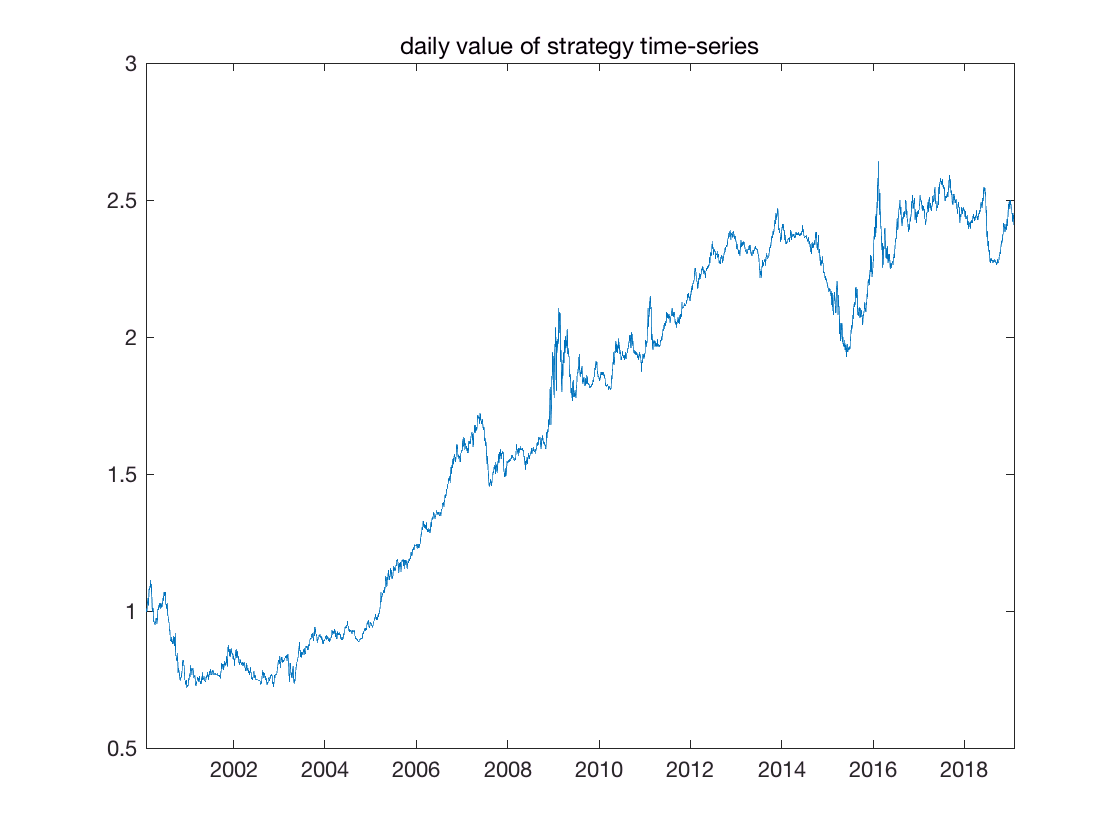


for i =1:n
value = [value; prod(temp(1:i))];
end

date= datetime(t2,'ConvertFrom','datenum')+calyears(1900);
figure
plot(date,value)
title('daily value of strategy time-series')

  %% Goal #2 Calculate the strategy's calendar year returns, i.e., cumulative returns in each year from 2000 to 2019.
  %% Compounding all of the daily returns in every calendar year to get the calendar year returns
  yr_ret=[];
  yr_date =[2000:2018]';
  for i =0:18
      yr_ret=[yr_ret;prod(c_pret((t_index(1+12*i):(t_index(1+12*(i+1)))-1)))-1];
  end

%%Print out calendar year return 
  array2table([yr_date,yr_ret],'VariableNames',...
    {'Year','Calendar_Year_Return'})

ans = 19×2 table
    Year    Calendar_Year_Return
    ____    ____________________

    2000      -0.23173          
    2001       0.10446          
    2002     -0.037113          
    2003      0.089882          
    2004      0.087229          
    2005       0.29018          
    2006       0.27557          
    2007     -0.019804          
    2008        0.2485          
    2009     -0.040789          
    2010      0.090535          
    2011      0.085067          
    2012       0.04352          
    2013      0.015563          
    2014      -0.07856          
    2015       0.13075          
    2016      0.012778          
    2017     -0.022205          
    2018    -0.0035489          


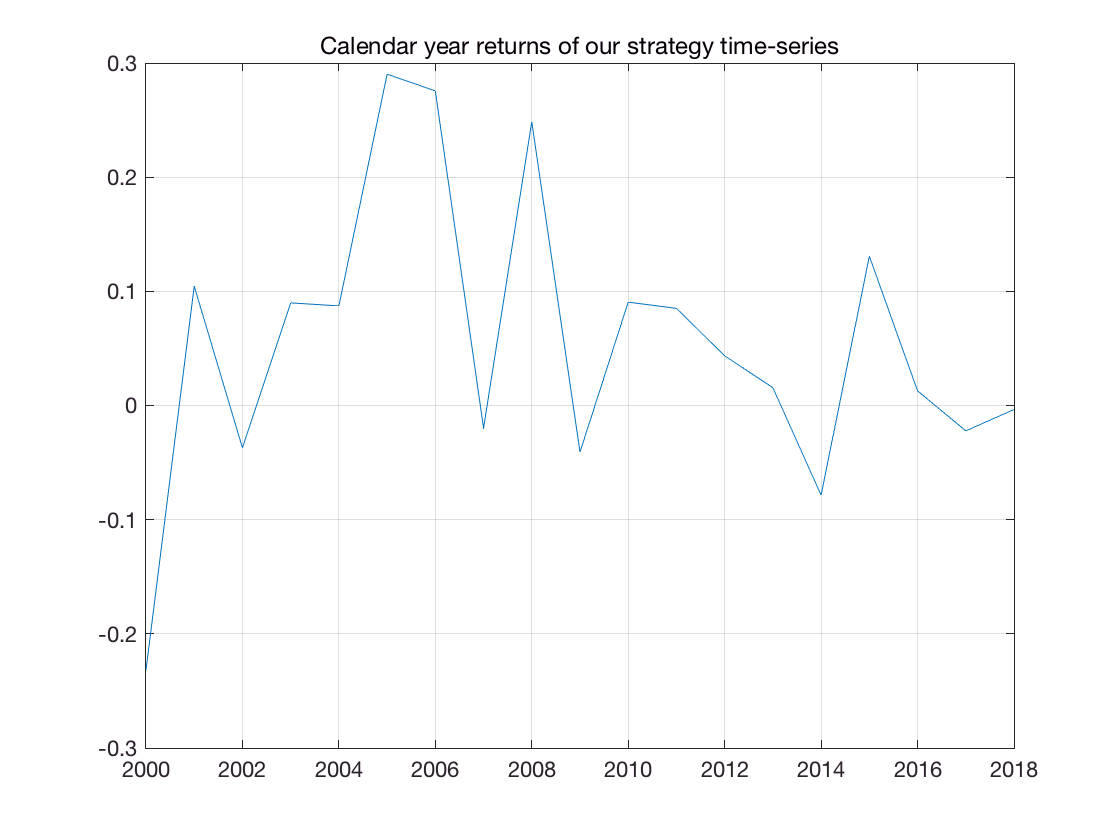

  
%% Plot Calendar year returns of our strategy
figure
plot(yr_date, yr_ret)
grid
title('Calendar year returns of our strategy time-series')  


%%Goal#3 Calculate the annualized return, annualized risk, and Sharpe ratio (let's assume risk-free rate of 0) of the strategy.

%calculate the annualized return(assume the annualized return is the geometric mean of the daily compounding returns to compounding 252 days for one year and then minus 1)
anual_ret=(geomean(1+pret))^252-1

anual_ret = 0.0458

%calculate the annula volatility of the strategy, there is two ways to calculate it, one is std( calender year return), which is too rough.  
%So I choose the second method: std(daily return)* sqrt(252)
anual_risk = std(pret)*sqrt(252)

anual_risk = 0.1131

% the sharpe ratio: since the risk-free rate equals 0, the sharpe raio = (anual_ret-0)/anual_risk
s_ratio=anual_ret/anual_risk

s_ratio = 0.4046

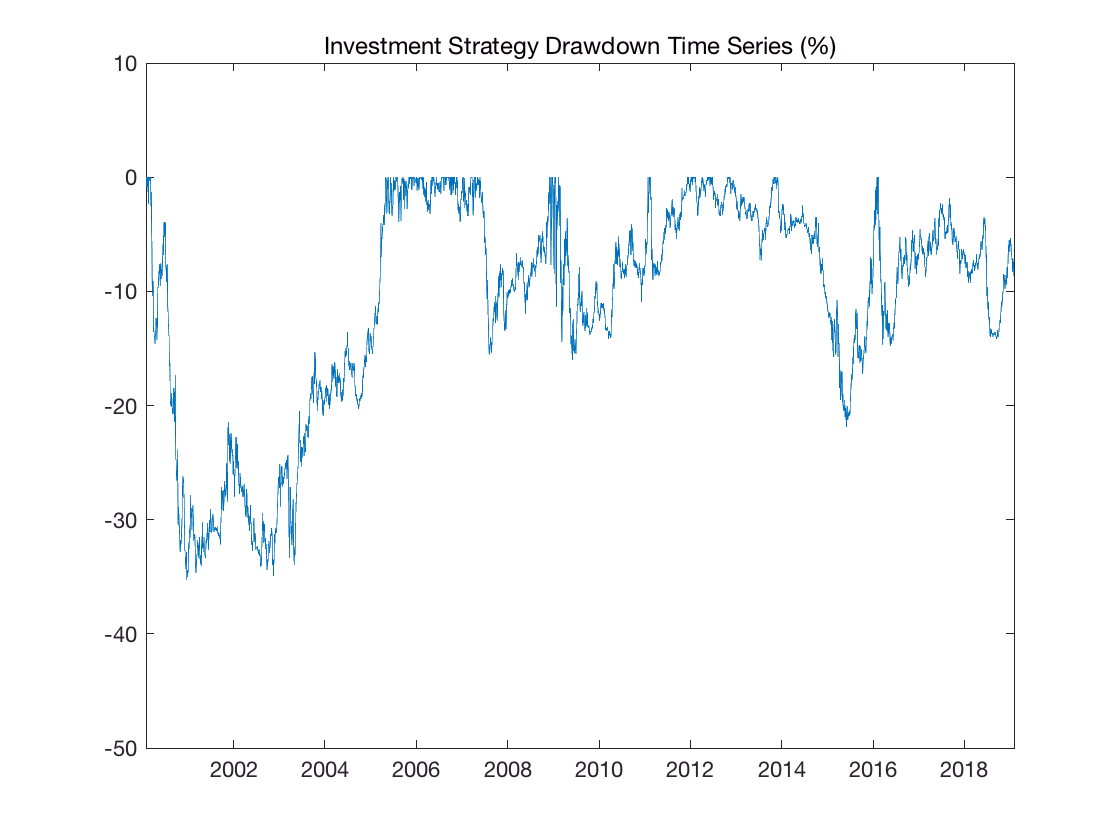


%%Goal #4 Identify the maximum drawdown period for this strategy.
%   we need first calculate the drawdown time series
drawdown_ts=nan(size(value));
for t=1:length(value)

    %   the high-watermark before the date
    tmp_max=max(value(1:t));
    
    %   skip if it's nan
    if isnan(tmp_max)
        continue;
    end
    
    %   drawdown from high-watermark to the current price
    drawdown_ts(t)=value(t)/tmp_max*100-100;
    
end

%   plot the drawdown time series
figure
plot(date,drawdown_ts);
ylim([-50 10]);
title('Investment Strategy Drawdown Time Series (%)')

%   let's locate the max-drawdown period
[maxdd,t_end]=min(drawdown_ts);
[blah,t_start]=max(value(1:t_end));
fprintf('MaxDD of %.2f%% starts at %s, ends at %s.\n',maxdd,date(t_start),date(t_end));

MaxDD of -35.29% starts at 03/08/2000, ends at 12/22/2000.
